*MAPS2001 project*

# Analysis of Atmospheric Stable Water Isotopes

## Abstract

*To be done later.*

## Introduction

Since 1970's, there has been an increased interest in investigation of fractionation of the isotopes occurring in the components of water, i.e. ${\mathrm{H}}^2$, ${\mathrm{H}}^3$ and ${\mathrm{O}}^{18}$. Most of the studies of these complex interactions between different parts of the atmosphere are based on the world-wide survey organized since 1961 by the International Atomic Energy Ageney (IAEA) and the World Meteorological Organisation (WMO). The analysis of tritium abundance in different parts of the world can be related to proposing solutions to hydrological problems (e.g. predictions of lakes drought). Furthermore, using the data for concentration of hydrogen and oxygen isotopes, it is possible to deduce various characteristics of the circulation patterns and mechanism of the global and local movements of water. [1], [2]

Here, working with Global Network of Isotopes Precipitation (GNIP) database, three separate-steps analyses have been provided.

The network of stations was initially created in 1958 with the goal of detecting atmospheric fallout from nuclear tests during the Cold War. Following this original purpose, simple analysis of Valentia Observatory GNIP station data was conducted, visualising the simple trends and correlations in abundances of ${\mathrm{H}}^2$, ${\mathrm{H}}^3$ and ${\mathrm{O}}^{18}$ in time.

Subsequently, reflecting the conversion of the network in the 1970's to support various hydrological studies, an attempt was made to investigate more complex, large-scale relationships between the isotope abundance and environmental factors. One model commonly incorporated to explain the global heavy water isotope precipitation is the Rayleigh fractionation [3], which is dependent on the ambient temperature. Consequently, some form of correlation between average annual temperature and isotope fractionation can be expected and it is demonstrated here how to visualise the same. Furthermore, a 2007 article by Lee et al. [4] reports the increase of ${\mathrm{O}}^{18}$ ratio with annual mean temperature to be approximately linear for regions with average annual temperatures of 15 °C or less. Following this information, the project aims to determine linear equations describing the temperature/isotope fraction correlation for all three isotopes and evaluate their goodness of fit. The structure of the computational methods chosen to achieve this are designed to be easily adaptable for other potentially influential factors like altitude or geographical coordinates.

Lastly, recent work has looked at stable water isotopes and large-scale vertical motions in the tropics to propose reasons for large atmospheric circulation in this region. [5] Following that, the specific graph of average deuterium abundance in precipitation for different intervals of monthly averages precipitation rates for East and West Pacific was reproduced from the paper. The aim was to produce and generalise the code which could be then further applicable to different regions as well. Similar analyses were therefore performed for the UK and the Ireland to identify any similar trends and some expected differences due to the different climate zone.

## Computational Methodology

## **        1. Simple Initial Analysis of Data (Valentia GNIP Station)**

First, to understand the format and to visualize the data, the Valentia Observatory (Ireland) was randomly chosen. Simple analysis has been conducted – trends and correlations in abundances of ${\mathrm{H}}^2$, ${\mathrm{H}}^3$ and ${\mathrm{O}}^{18}$ in time.

IAEA WISER data for Valentia GNIP station was downloaded and imported to MATLAB.

clear all
clf
v = 'valentia.xlsx';

Readtable function was used to easily extract data from the Excel file.

s = readtable (v); % reading data from the specific Data File

IAEA WISER GNIP date were found to be not in a chronological order. To easily manipulate the data in general, the sorting function had to be invented and used.

%%% sorts the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); % sorts A array (708x1 - includes only dates) into ascending order
                                   % originalIndex gives the original index or s table

sortedS=s(originalIndex,:); % prints table with originalIndex, which gives data in ascending date

Saving measurements for deuterium, tritium and oxygen as variables:

% convenient labelling of variables
H2 = sortedS.H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

Deuterium variance with respect to time:

figure (1)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')



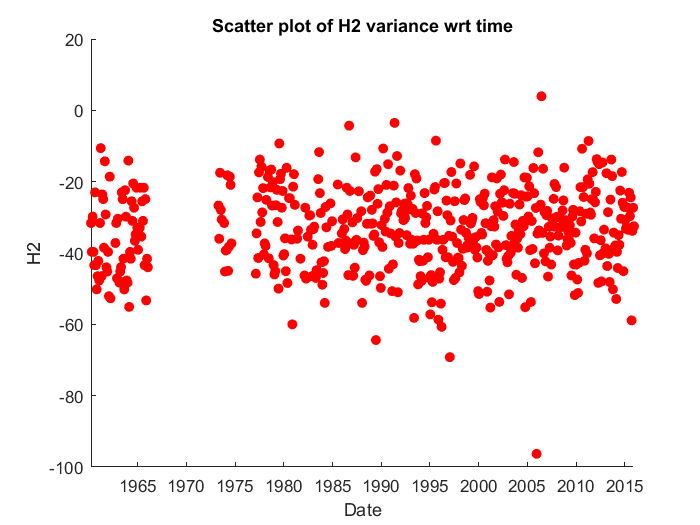

Similar scatter plots have been produced for tritium and oxygen.

## **        2. Comparison of Isotope Precipitation Rate to Average Annual Temperature Word-Wide and Visualising Possible Correlation**

The first hurdle to conquer when investigating world-wide trends was managing large amounts of data with concise coding. To be able to work with statistically relevant sample sizes, almost the entire GNIP database as well as temperature records from the World Bank Group Climate Change Knowledge Portal were downloaded by country and had to be imported into the workspace:

% the following path has to be adjusted for each user!
source_dir = 'path adjusted for each user';

% load all .xls files (the climate data) into one cell array
AATdata=loadfiles(source_dir,'*.xls');

% load all GNIP .xlsx files (the isotope data) into one cell array
Isotopedata=loadfiles(source_dir,'*xlsx');

The function 'loadfiles' was written specifically for loading a large number of excel tables into MATLAB, and defined at the end of the script as follows:

function loadedfiles=loadfiles(filepath, filextension)  % the complete file path and file extension are needed
    
source_files = dir(fullfile(filepath, filextension));   % the fullfile function merges file name fragments and the dir function lists all files the thereby specified folder which have the given extension
loadedfiles=cell(size(source_files));                   % precreate an empty cell array for all files to be loaded
      
    for i = 1:length(source_files)
      loadedfiles{i} = readtable(fullfile(filepath, source_files(i).name));  % one by one, every excel file identified above is loaded into Matlab using the readtable function
    end
end

Each cell in either of the cell arrays 'Isotopedata' and 'AATdata' were design to correspond to the GNIP data or climate data for one country.

A scatter plot of the heavy isotope fraction against temperature was believed to be a good measure to get a first impression of the nature of correlation (if there is any at all). To produce such a plot, averages over the isotope and temperature values had to be calculated for each country. Although only calculations for median values were presented here, mean values were calculated with the same method: 

% calculate the medians for H2, H3, O18 and temperature across a country for all datasets
means=zeros(size(Isotopedata,1),4); % creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};     % the for loop will repeat the data collection for every country               
   tempdata=AATdata{i,1};
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   % calculates medians for the isotopes ignoring NaN values
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    % calculates medians for temperatures ignoring NaN values
   
end  

According to G Torri et al. [5] , the abundance of heavy isotopes is usually measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of the heavy isotope to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\mathrm{ppm}$$
 

In the original Excel file downloaded from GNIP database, the tritium abundance was not given in $\delta \mathrm{D}$ units but in TU (Tritium atoms per 1018 Hydrogen atoms), so $\delta \mathrm{D}$ had to be calculated before proceeding:

vsmow=1.85*10^-11;   % given in ppm for tritium
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;

Scatter plots were produced for all three isotopes: 

% exemplary code to plot scatterplots of isotope concentration in precipitation vs temperature

figure(1);
scatter(medians(:,4),medians(:,1));     % H2 median values
xlabel('Average Temperature in °C');    % this labels the graph with all relevant information
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

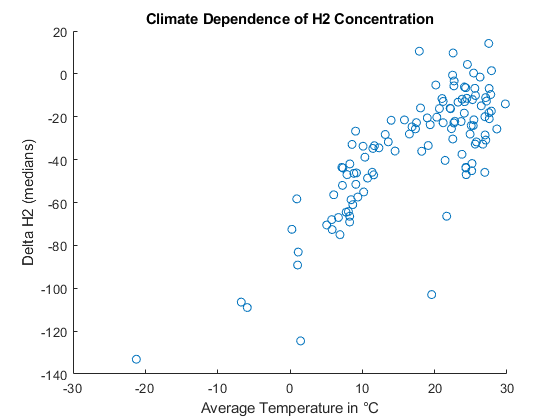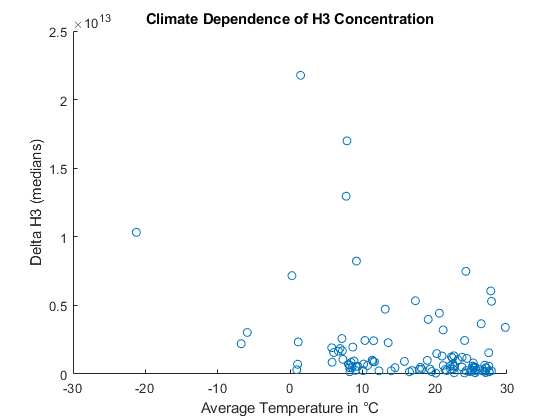

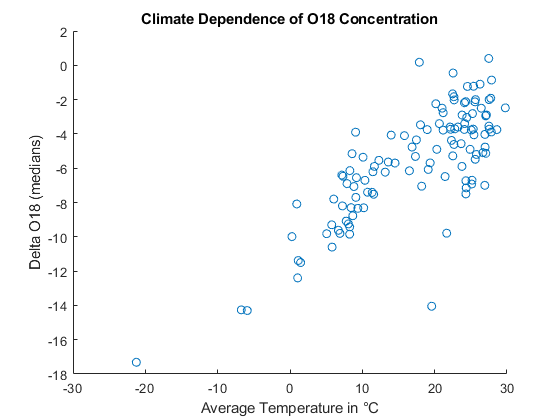

The scatter plots made evident that while there appeared to be a roughly linear relationship for ${\mathrm{H}}^2$ and ${\mathrm{O}}^{18}$, the ${\mathrm{H}}^3$ abundance in precipitation could not be easily be related to temperature. It was also visible that the scattering became significantly more random for high temperatures, which agreed with reference article by Lee et al. [4]. A cut-off temperature of 15 °C was set, so in order to fit a regression line to the data, only data points with temperatures below 15 °C were consider for the next step of the analysis:

% collect all median values for temperatures below 15°C only

n=1;
for k=1:length(medians)
    if medians(k,4)<=15
        behavedmedians(n,:)=medians(k,:);    % medians that theoretically follow the relationship are added to a new array
        n=n+1;
    end
end

Lastly, the curve fitting toolbox was utilised to fit a first-degree polynomial (i.e. a linear regression line) to the selected data range. This happened within a special function which not only fitted a regression line to one dataset against temperature, but that also accepted several input arrays as possible y-values, compared the goodness of fit for each and only returned the fitted curve with the best fit. The goodness of fit was assessed by comparison of the coefficient of determination R², which is the proportion of variance in the dependent variable that is explained by the independent variable, hence a high R² indicated a good fit.

function bestfit=fitfunction(X,varargin)    % fitfunction accepts a variable number of input arguments
    
    gof=zeros(length(varargin),1);          % create an empty array to hold the coefficients of determination for later comparison
    
    for i=1:length(varargin)                % for every given possible y-value dataset...
        [~, gofi]=fit(X,varargin{i},'poly1');   % ...a 1st degree polynomial is fitted...
        gof(i)=gofi.rsquare;                % ... and the coeffitient of determination is retained
    end
    
    [bestgof, gofnb]=max(gof);              % the y-value dataset which provides the highest R² (--> the best fit) is determined
    coefficients=fit(X,varargin{gofnb},'poly1'); % calculate the coefficients for the linear equation describing the best fit
    
    bestfit={coefficients,bestgof,gofnb+1};   % the function outputs the best fit coefficients, the corresponding R² and the number of the input variable that provides the best fit
end

This function was simultaneously used on the mean and median values for ${\mathrm{H}}^2$ and ${\mathrm{O}}^{18}$ in the temperature range of interest:

BestFit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1),behavedmeans(:,3),behavedmedians(:,3))

Which provided the following result:

`BestFit = 1×3 cell array`

`    {1×1 cfit}    {[0.8012]}    {[4]}`

`Coefficients = `

`     Linear model Poly1:`

`     Coefficients(x) = p1*x + p2`

`     Coefficients (with 95% confidence bounds):`

`       p1 =      0.4499  (0.3801, 0.5197)`

`       p2 =       -11.8  (-12.43, -11.16)`

The result meant that the mean values of ${\mathrm{O}}^{18}$ most closely correlated to the mean annual temperature, i.e. this graph was chosen for plotting:

figure(2);18
plot(BestFit{1},behavedmeans(:,4), behavedmeans(:,3));      % plot the linear regression line as determined before for the best fitting pair of datasets
xlabel('Average Annual Temperature in °C');                 % label the graph appropriately
ylabel('Delta D O18 (means)');
title('Best Fitting Linear Regression Line: O18 (means)');

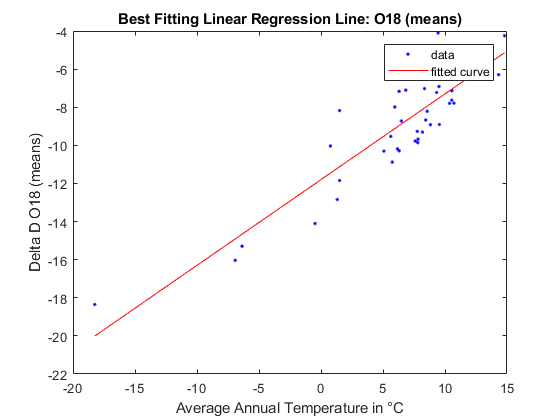

## **        3. Reproduction and Generalisation of the Code for the Graph of Average Deuterium Abundance In Precipitation for Different Intervals of Monthly Averages Precipitation Rates**

To reproduce and generalise the code which could be then further applicable to different regions as well, the plot from page 3714: $\delta \mathrm{D}$ vs. precipitation rate per day:

[5]* G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017*

was replotted.

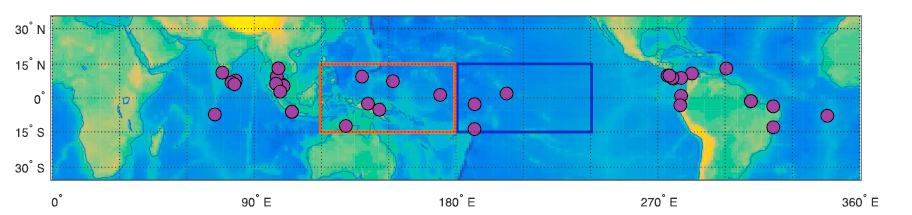

The data from IAEA WISED database for West and East Pacific was donwloaded accordingly:

**West:** (15° N - 15° S, 120° E - 180° E): Darwin, Jayapura, Madang, Tarawa, Truk, Yap

**East**: (15° N - 15° S, 180° E - 240° E): Apia, Canton Island, Christmas Island,

and imported to MATLAB. Readtable function was again used to easily extract data from downloaded Excel files, and the data was sorted chronologically using a sorting function (used in 1)).

To find general trends for these two areas (East and West), all data has to be concatenated first. To do this, the comment column was removed, as some of the downloaded station data had no data in this column, and so the column did not exist in the data when converted to a table. This only affected the data for West, so the comment column was removed from this data. However, when the section was run again without re-importing the western datasets, MATLAB did not understand the non-existence of this variable. Therefore, this process is done only if the data actually exists (if it exists for the first one, it is assumed that it exists for all).

A=any(strcmp('Comment',fieldnames(w1)));
B=any(strcmp('Comment',fieldnames(w2)));
C=any(strcmp('Comment',fieldnames(w3)));
D=any(strcmp('Comment',fieldnames(w4)));
E=any(strcmp('Comment',fieldnames(w5)));
F=any(strcmp('Comment',fieldnames(w6)));
ABCDEF=[A,B,C,D,E,F];
if any(ABCDEF) == 1
w1.Comment=[];
w2.Comment=[];
w3.Comment=[];
w4.Comment=[];
w5.Comment=[];
w6.Comment=[];
end

Also, some figures were set to refer back to a certain graph when specifying certain properties and data.

wFull=[w1;w2;w3;w4;w5;w6]; % concatenating the data from the various western stations
eFull=[e1;e2;e3]; % doing the same for east

figureNumScatter=10;
figureNumBins=20; 
% setting figure numbers for the two graphs

The loop was  used to plot the graphs twice, switching between East and West each time.

for j=[1,2]
 if j==1
     % for the Eastern Loop
     s=eFull;
     pointColour='xblack';
     barColour='blue';
     
 else
     % Western loop
     s=wFull;
     pointColour='.red';
     barColour='yellow';
     
 end

Next, the relevant data was retrieved. As the precipitation per day was supposed to be plotted, and months are different lengths, the number of days for the period when each reading was taken over was calculated, and this fact was further used to determine the average precipitation per day. Note that this had to be done via dividing total precipitation by number of days, as there was not any more temporal resolution than this.

% retrieving relevant data
d=datenum(s.Date,'yyyy-mm-dd');
H3=s.H3;
H2=s.H2;
O18=s.O18;

% days in month
numdays=(datenum(s.EndOfPeriod, 'yyyy-mm-dd')- datenum(s.BeginOfPeriod,'yyyy-mm-dd')+1);

% precipitation per day
pppday=s.Precipitation./numdays;

First, the scatter plot was plotted to visualize the unbinned data and to decide on the bin size.

% see a scatter plot of the data
figure(figureNumScatter)
hold on
plotObjectpppD(j)=plot(pppday,H2,pointColour);
title('Delta Deuterium vs. Precipitation Rate: Scatter plot')
hold off
xlabel('Precipitation rate (mm per day)')
ylabel('\delta D')

The original graph was plotted using bins of five with the final bin stretching to infinity.

% deciding our bin sizes
Edges=[0,5,10,15,20,Inf];

To do these steps,  the $\delta D$ data must have been discretized by its relevant precipitation per day data.

% finding out which deltaH2s fall in each ppt/day
[pppdaybin,Edge]= discretize(pppday,Edges);

% pppdaybin = which 'bin' each pppday in the array falls in
% to get the array of deltaH2 for each bin

Next, the loop was used in order to sparate out each binned set of data:

for i=1:(length(Edge)-1)
    
% using a structure as it is easier to use with loops
% making the struct separated by bin

H2binned(i).H2=H2(pppdaybin == i);
end

And another loop was used in order to find the means for each bin:

for i=1:(length(Edge)-1)
% finding the mean of these binned deltaH2 (along with the standard deviations)
    H2binned(i).mean = nanmean(H2binned(i).H2);
    H2binned(i).error = nanstd(H2binned(i).H2);
end

Whilst structures generally work more quickly with loops, arrays are slightly easier to do basic data manipulation with, so the data is was converted back into an array.

for i=1:(length(Edge)-1)
% switching these back to an array, so we can more conveniently use this data (ouside of loops)
    H2binnedmeans(i)=H2binned(i).mean;
    %here we use the standard error, as opposed to just the standard deviation of the dataset
    H2binnedmeanstandarderror(i)=(H2binned(i).error)./sqrt(length(H2binned(i).H2));
end

The original graph was reproduced plotting the mean $\delta \mathrm{D}$ binned, versus the midvalue of each bin. Note that for the last bin, the first bins midvalue was added to the beginning of the last bins first edge.

To find the midvalue:

% getting an array of the midvalues and creating an array of the start and end points of each bin, and then mean them

MidEdge(1,:)=Edge(1:(length(Edge)-1));
MidEdge(2,:)=Edge(2:length(Edge));
MidEdge=mean(MidEdge);
% redefining the mid edge for the final bin
MidEdge(length(Edge)-1)=MidEdge(1)+Edge(length(Edge)-1);


Finally, the bar function was used to produce similar bars as in the original graph. For the bars to not overlay each other, their position was adjusted depending on which loop cycle the code is on.

% plotting the graph, and use 'bar' function to plot as bars (as in the original paper)

if j==1
% shifting the bars for the first loop (East) to the negative
    MidEdgeShift=-1;
else
% and the bars for the second loop (West) to the positive
    MidEdgeShift=1;
end 
% plotting a bar graph
figure(figureNumBins)

To make the plot look little 'prettier':

% including earlier calculated shift
pointPosn=MidEdge+MidEdgeShift;
hold on

% creating a bar object so we can edit its properties
b(j)=bar(pointPosn,H2binnedmeans);

% adjust its width to allow us to see both bars at once, 
% and differentiate the colours we picked earlier
b(j).BarWidth=0.4;
b(j).FaceColor=barColour;
% to include errors, so we create an error bars object, and plot on the same graph
e=errorbar(pointPosn,H2binnedmeans,H2binnedmeanstandarderror);
% We remove the line and points of this 'second' graph, as we only want the error bars
e.LineStyle='none';
e.Marker='none';

At the end, all necessary details for the graph (title, axes labels, etc.) were included.

title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

xlabel('Precipitation rate (mm per day)')
ylabel('\delta D (per mil)')
xticklabels(Edges)
xlim([0,25])
ylim([-60,10])
grid on
hold off

end
legend (b,'Eastern', 'Western', 'Location', 'northeast' )
legend (plotObjectpppD,'Eastern', 'Western')


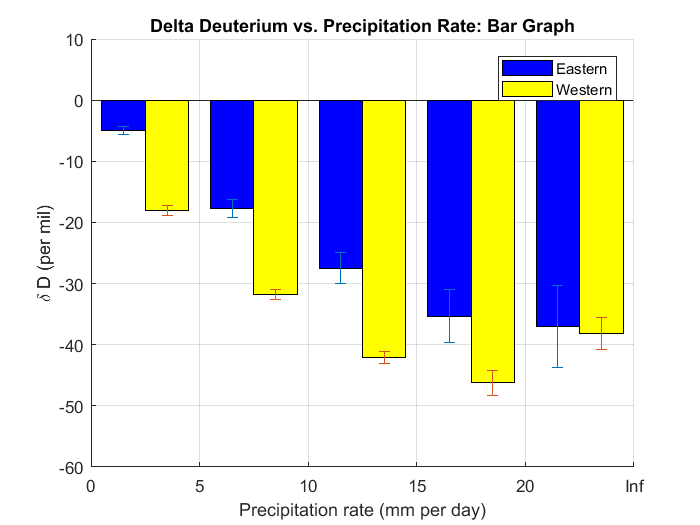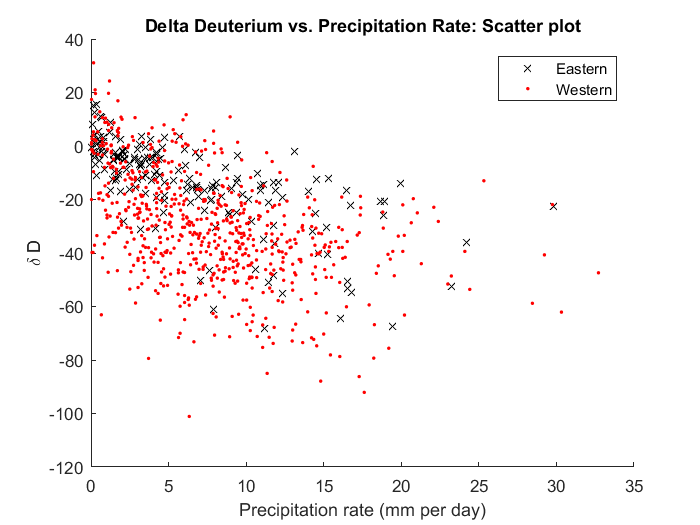

The next step was to repeat the same analysis for other isotopes, the UK and other geographic regions, i.e. Ireland.

The similar code was used, in a separate function file, to produce similar results for the UK, and identify any similar trends; however, as the UK lies in a different climate zone, some differences are expected to be seen.

ukgraphsfunction('GeographicUK.xlsx');

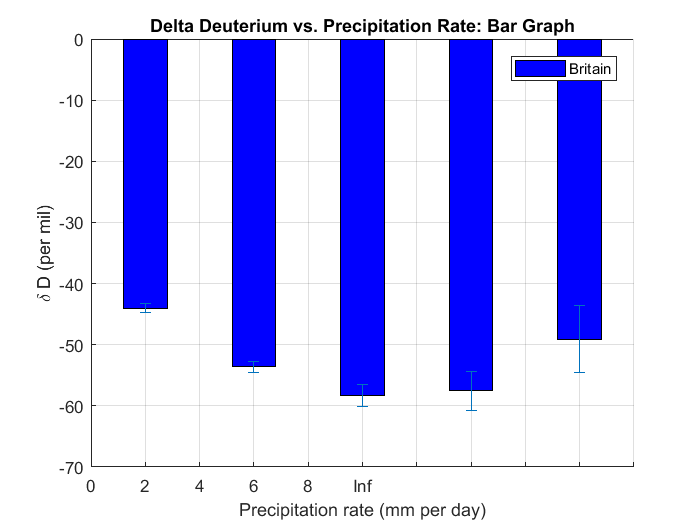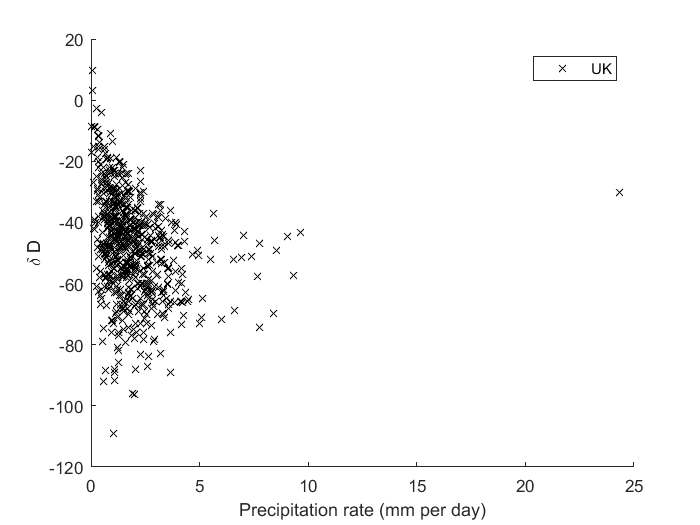

Finally, the larger of the British Isles (Britain and Ireland) were compared to see if there were any significant differences, potentially due to geographic positioning.

BIgraphsfunction('GeographicUK.xlsx','Ireland.xlsx')

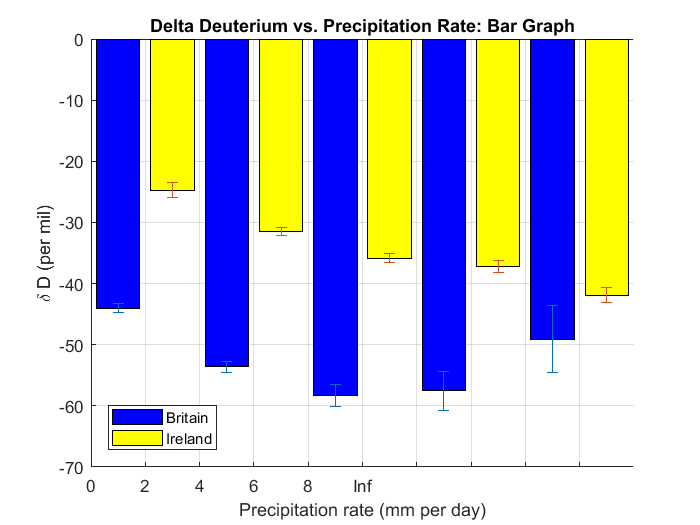

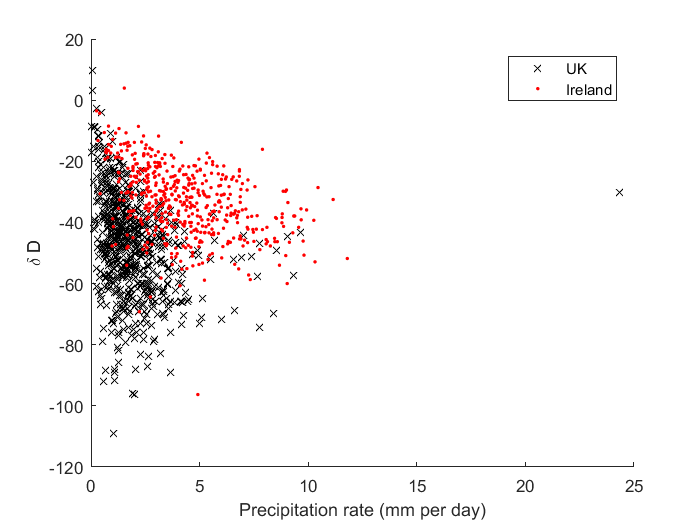

## Critical Discussion of Results

## **        1. Simple Initial Analysis of Data (Valentia GNIP Station)**

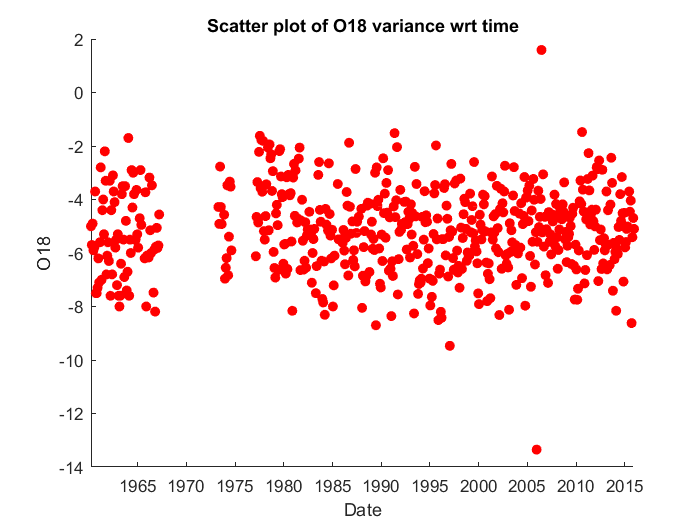

Based on the plotted graphs of ${\mathrm{H}}^2$and ${\mathrm{O}}^{18}$  with respect to time, a stable linear trend was observed with a few potential outliers in 2005. 

Further investigation of these potential outliers in 2005 revealed that Valentia Island was both the warmest and the wettest place in Ireland and exceptional compared to years on record. Annual rainfall of 1458 mm was reported with an average temperature of 11.4 °C according to Met Eireann’s end of year report. [6] The possible correlation between the abundances of deuterium and oxygen dependence on temperature and rainfall was suggested for future work to provide the thorough analysis. 

Missing data in the retrieved Excel files from the Global Network of Isotopes Precipitation (GNIP) database from the time-period around the year 1970 caused a visible gap in the both graphs.

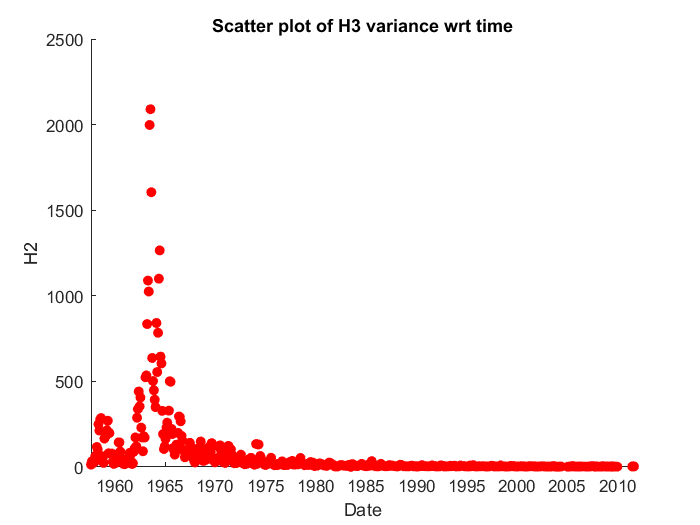

For the abundance of tritium, completely different trend is visualised. A non-standard peak in the abundance of tritium was observed between the years 1960–1965. This observation precisely follows the original purpose of the network of stations to detect atmospheric fallout from nuclear tests during the Cold War, as tritium is an essential to the type of fusion used in nuclear weapons design. 


$${\mathrm{Li}}^6 +\mathrm{n}\longrightarrow {\mathrm{He}}^4 +{\mathrm{H}}^3 +\mathrm{energy}\text{ }\left(5\text{ }\mathrm{MeV}\right)$$


Tritium is made by bombarding lithium ${\text{Li}}^6$ with a neutron ($\mathrm{n}$) which causes the lithium nuclei to split, producing helium ${\text{He}}^4$, tritium${\mathrm{H}}^3$ and energy. [7]

Begemann & Libby (1957) estimated that 1.1 kg of tritium was released to atmosphere for each megaton thermonuclear explosion. By 1965, the nuclear tests were estimated to have a fusion yield over 300 megatons. [8] 

Extended depiction of the abundance of tritium in the atmosphere is therefore mainly thought to reflect the rapid increase of nuclear test in 1950’s and early 1960’s. The increased detection of tritium could be also further influenced by cumulative re-evaporation from land and long residence time of tritium isotope of water in the sea (compared with the radioactive half-life of tritium), as the analysed GNIP station (Valentia Observatory) lies on the southwest coast of Ireland (factors up). [9] The concentration of tritium in rain at Valentia in this time-period was estimated to reach 1000 megatons.

## **        2. Comparison of Isotope Precipitation Rate to Average Annual Temperature Word-Wide and Visualising Possible Correlation**

A linear relationship described by $\delta \mathrm{D}\left({\mathrm{O}}^{18} \right)=0\ldotp 4499\cdot \mathrm{T}-11\ldotp 8$ was found as the best fit across all analysed data, where $80\ldotp 12\text{ }%$ of the variance in $\delta \mathrm{D}$ were confidently predicted by the temperature. This fit was good enough to successfully validate a temperature dependence in the isotope fractionation for temperatures below 15 °C, but in comparison with literature values [4], it was still relatively unprecise. Lee et al. observed a relationship of the form $0\ldotp 69\cdot \mathrm{T}-14\ldotp 49$ with a coefficient of determination of $98\text{ }%$, quite different and with much less uncertainty than what was found here. The discrepancy most likely stemed from the measures taken to simplify the analysis: 

- While the isotope values were recorded at usually only a few locations per country, the average temperature was taken for the whole country. An alternative option would be to receive the temperature data from the GNIP datafiles for the specific locations of measurement, but not all stations included air temperature in their datasets, which significantly reduced the available sample size. Furthermore, it was by no means guaranteed that the included air temperatures gave an accurate account of the annual temperature, for example, one station in a hot climate might have recorded the temperature in the colder hours of the morning and report the same average temperature as a station in a colder climate which took measurements around the time when daily temperatures peak.

- The size of the countries wass neglected and each one was summarised to one data point, which caused large errors for countries like the USA or Russia that potentially span several climate zones. For increased precision, data should be grouped in smaller geographic regions or by climate zone. Ideally, each station would be plotted against the local average temperature on its own.

- The annual temperature was (with a few exceptions) averaged over 30 years between 1960 and 1990, while part of measurements was from more recent decades. Climate change might have caused distortion in relationship under these conditions.

- Some countries have stations in locations that are allocated to a certain country in the GNIP database and therefore went into the calculations for this country, although they geographically lie in an entirely different climate zone (for example: Saint Helena in the South Atlantic Ocean provided misleading measurements for a 'UK climate').

Noting that with he shown procedures, an analysis of the deuterium precipitation with temperature gave a regression line with comparable precision ($78\ldotp 67\text{ }\text{ }%$). Only tritium did not display such a correlation. The most probable explanation was believed to be as follows: When considering the relative amounts of heavy isotopes against normal water isotopes, tritium is less abundant than deuterium or ${\mathrm{O}}^{18}$ by several orders of magnitude (for tritium compared to for deuterium). The smallest inaccuracy, sample contamination or human made or natural, temperature independent nuclear activity heavily disturbs a natural tritium distribution. The GNIP itself pointed out that for several stations the tritium values substantially exceeded the expected figures, most likely due to local technogenic tritium or significant contamination of the sample collection. [11]

The last question remaining was, why did a temperature dependence occur at all? To understand this, one must have considered the Rayleigh fractionation [3], describing the change in isotope ratios of an open system subject to fractional distillation (for example when the vapour phase condenses in clouds and leaves the system as rain). Heavy isotopes like ${\mathrm{H}}^2$ and ${\mathrm{O}}^{18}$ tend to leave the vapour phase earlier/at higher temperatures than normal isotopes due to their higher mass (a higher boiling point). Consequently, cold air masses are less likely to hold evaporated heavy isotopes, they only evaporate in warm conditions and rain out when the air cools down. 

However, as Lee et. al. pointed out, while being the most widely applied explanation for global isotope distributions, Rayleigh fractionation does not explain all trends. [4] As apparent in the obtained scatter plots, the effect of the high mass isotopes on solubility in air became negligible for high temperatures, i.e. above 15 °C a slightly higher boiling point for heavy isotopes was found to be irrelevant. Instead, other factors like surface fluxes played a much bigger role in the saturation of heavy isotopes in precipitation. It was therefore of special interest to conduct analysis of the isotope fractionation of hot zones like the tropics, which is explored in section 3 of this report.

## **        3. Reproduction and Generalisation of the Code for the Graph of Average Deuterium Abundance In Precipitation for Different Intervals of Monthly Averages Precipitation Rates**

Original plot of $\delta \mathrm{D}$ vs. precipitation rate per day from page 3714 of [5]* G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017:*

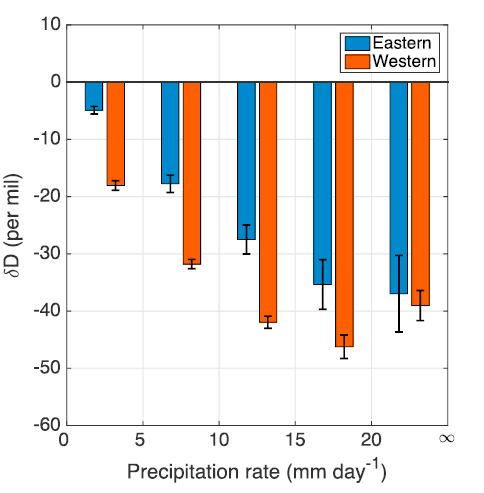

The plot obtained with the reproduced and generalised code:

In tropics, the concentration of the isotopes has a negative correlation with the amount of precipitation that falls and is termed “amount effect”. This is largely due to isotopic depletion as the condensation progresses [1]. It was found that vertical structures vary greatly from one geographic region to another. Interestingly, Eastern and Western Pacific have a different vertical structure. Although the whole region was believed to have top heavy profile, recent studies showed that Eastern Pacific is more bottom heavy. [5]

Whilst the graphs were slightly different, this was only due to layout and sizing differences, and the actual data represented by them was the same. Interestingly, this was despite the original paper using a reduced date range, in order to use other datasets along with it. Therefore, it suggested that the authors of the paper may not have reduced the date range for plotting these bar graphs.

Considering the equivalent graphs for the British Isles:

Some major differences with the data from the tropical regions were identified. The minima of was observed at a lower precipitation rate (the bin 4-6mm per day for Britain versus the bins >15mm per day for the tropical regions) and was itself lower than in the tropics. 

This suggested there was a greater 'amount effect' in the UK than the tropics. Looking at the comparison with Ireland, the difference seen was similar; lower, and earlier minima for the UK than Ireland. This suggested a more bottom-heavy atmosphere in Ireland; the reasons for this remained unclear and were suggested for future work to provide the thorough analysis.

## Conclusions and Future Work

**Conclusions**: *To be done later.*

**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

In conclusion it can be said that the average local temperature does influence the global isotope distribution to a significant degree, it is therefore definitely worth studying the same. The present analysis is, however, only suitable to validate general trends, the numerical results do not have a statistical certainty high enough to be considered reliable yet. Future efforts based on this work could include a finer geographic separation of the GNIP stations so that the mean isotope values and temperatures are calculated for smaller areas. In fact, work towards this goal has already begun (see full code file), but is not completed yet. However, as influential as temperature has proven to be, the established computational methodology can easily adapted to investigate possible correlations between other environmental factors too, for example altitude, latitude or vapour pressure. Overall, Matlab has proven to be a very suitable tool for this type of analysis.

The next step in the processing of global isotope data is visualising the distribution with the mapping toolbox, which has also been partially attempted already (see full code file). A first goal in this section would be to mark all GNIP stations on a global projection and indicate trends in average isotope precipitation with different colours. Initially, the stations would be represented by points, but Matlab also facilitates the production of texture maps with more fluid transitions. Apart from heavy isotope fractions, the previously named possible influential factors like temperature or altitude can be depicted in the same way. The final step would be to compute geolocated grids containing the relative differences between isotope fraction and influential variable and project these on a global map. This way, more regions of interest like the tropics where commonly accepted relationships do not hold can easily be found and graphically represented. 

**PART 3**

In part 3, we successfully reproduced a graphical representation of the data similar to one in our original research paper. This was then used to analyse the datasets from the UK and Ireland, and compare them, identifying key differences and preliminary discussion of the root causes for these climatological differences. We saw that, when considering the British Isles as a whole, and looking at $\delta D\text{ }$versus precipitation per day, there was a significant difference to the profile of the tropics, with the minima of $\delta D$being more negative and occuring at a lower precipitation rate than in the ropics. We hypothesised that this data suggested a more top heavy atmosphere over the British Isles, however this could have been due to other factors that we are unaware of. We also saw that, within the British Isles, Ireland had data that sugested a more bottom heavy profile than Britain. We were unsure of why this would be the case, however possible explanations include the fact that the prevailing winds across the British Isles are usually from the West/South-West, and so generally pass over Ireland before Britain. This leads to Ireland having a higher average rate of precipitation per day, as the moist air flowing in from the Atlantic will begin to precipitate as it rises on impact with the landmass of Ireland.This thus may shift the data for Ireland, leading to the appearance of a comparatively more bottom heavy region.

**Future work:**

- include the investigation of the data sets from tropics for Tritium and Oxygen 18 isotopes

- for Valentia and other areas: provide thorough analysis of deuterium and oxygen abundances dependence on temperature

For project part 2)Temperature Dependence:

Check whether GNIP temperatures provide a smaller variance for the correlation

Plot only the temperature range where the relationship holds (<15°C) and plot a line of best fit. Determine the variance. 

Use the mapping toolbox to visualise both datasets (Isotope concentration and temperature) on a world map. Reproduce the map from the reference where the difference between relative temperature and relative Isotope concentration is depicted. (Might not have time for this, would be future work) Determine regions beside the tropics where the correlation does not hold.

Following from the work done in part 3) a major area of future development would be to look at increasing the spatial resolution of our datasets across the geographic regions we are interested in (in this case the British Isles), as we currently have the data from all of the stations in the geographic area collected together. This does not allow us to see the differences in the microclimates across the area, and so we do not receive a distinct picture of the isotopic profile of these regions. Therefore, a future avenue of exploration would be to re-separate the collection stations' data, and consider the isotope profiles across the British Isles in as much spatial resolution as possible. This would potentailly lead to a better comparison of results, and allow us to better judge the geographic trends, and promote a better analysis of the causes of the varying isotopic profiles. 

In a similar vein, this section only considered the relationships between $\delta D$ and average precipitation rate per day. A wider comparison taking into account multiple variables such as wind speed/direction and pressure would allow a more nuanced view of the factors correlating with the variances in $\delta D$, allowing greater confidence in conclusions, and potentially allowing a better model of isotopic effects in the atmosphere to be created. Additionally, we have only considered deuterium in these representations, however this could be expanded to include isotopes of oxygen, and also tritium (although, due to its sensitivity to human actions, commented on in part 2, tritium may be less suitable for analysis of climatological effects), and note differences/similarities of the trends in these.

The larger overall step would be to use these techniques to analyse the isotope profiles of multiple countries, eventually being able to consider the spread of data across the entire world (or, at least those areas with an ongoing isotope collection station that reports data to the database used for these calculations), and its climate regions. This would allow comparison and consideration between differing and similar climatological areas. These steps would thus ultimately allow an increased depth of modelling and analysis of the total atmosphere, potentially enabling greater accuracy of forecasting, which is a vital application in the modern society.

**REFERENCES:**

[1] Dansgaard, W. (1964). Stable isotopes in precipitation. *Tellus*, 16(4), pp.436-468.

[2] En.wikipedia.org. (2018). *Tritium*. [online] Available at: https://en.wikipedia.org/wiki/Tritium [Accessed 14 Mar. 2018].

[3] Kendall, C. and McDonnell, J. (n.d.). *Isotope Tracers in Catchment Hydrology*. pp. 51-86.

[4] Lee, J., Fung, I., DePaolo, D. and Henning, C. (2007). Analysis of the  global distribution of water isotopes using the NCAR atmospheric general circulation model. *Journal of Geophysical Research*, 112(D16).

[5] Torri, G., Ma, D. and Kuang, Z. (2017). Stable water isotopes and large-scale vertical motions in the tropics. *Journal of Geophysical Research: Atmospheres*, 122(7), pp.3703-3717.

[6] Met Eireann (2005). *Annual Report*. [online] Valentia Observatory. Available at: https://www.met.ie/publications/met_ar2005.pdf [Accessed 18 Mar. 2018].

[7] En.wikipedia.org. (2018). *Nuclear weapon design*. [online] Available at: https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production [Accessed 14 Mar. 2018].

[8] Begemann, F. and Libby, W. (1957). Continental water balance, ground water  inventory and storage times, surface ocean mixing rates, and world-wide  water circulation patterns from cosmic ray and man-made tritium. *The International Journal of Applied Radiation and Isotopes*, 2(3-4), pp.263-264.

[9] Chamberlain, A. (2004). *Radioactive aerosols*. Cambridge, UK: Cambridge University Press.

[10] Sdwebx.worldbank.org. (2018). *Downscaled Data Download*. [online] Available at: http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical

[11] Www-naweb.iaea.org. (2018). *Water Resources Programme - Global Network of Isotopes in Precipitation*. [online] Available at: http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html